clc; close all; clear;

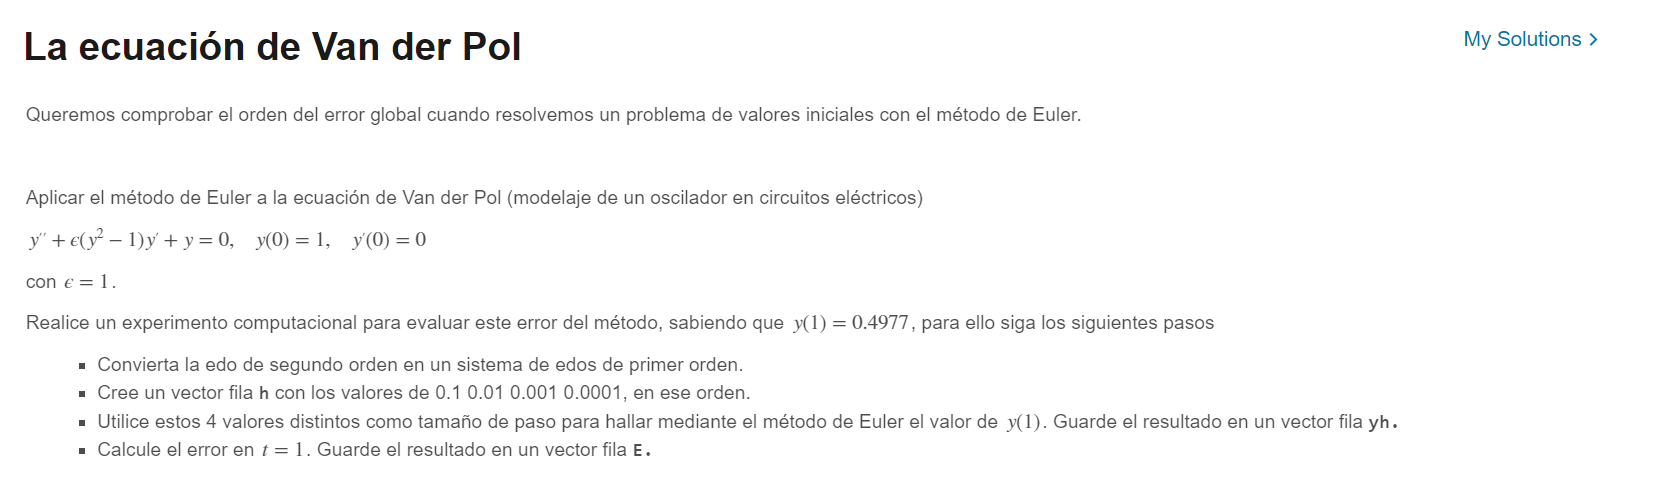

syms x y
f=y

$$f = y$$

g=-x-(x^2-1)*y

$$g = -x-y\,\left(x^{2}-1\right)$$

a=0; b=1; f0=1; g0=0;
h=[0.1 0.01 0.001 0.0001];
y1=euler(f,g,a,b,f0,g0,h(1),b);
y2=euler(f,g,a,b,f0,g0,h(2),b);
y3=euler(f,g,a,b,f0,g0,h(3),b);
y4=euler(f,g,a,b,f0,g0,h(4),b);
yh=[y1 y2 y3 y4]
E=[abs(y1-0.4977) abs(y2-0.4977) abs(y3-0.4977) abs(y4-0.4977)] %error absoluto o relativo, dios sabra

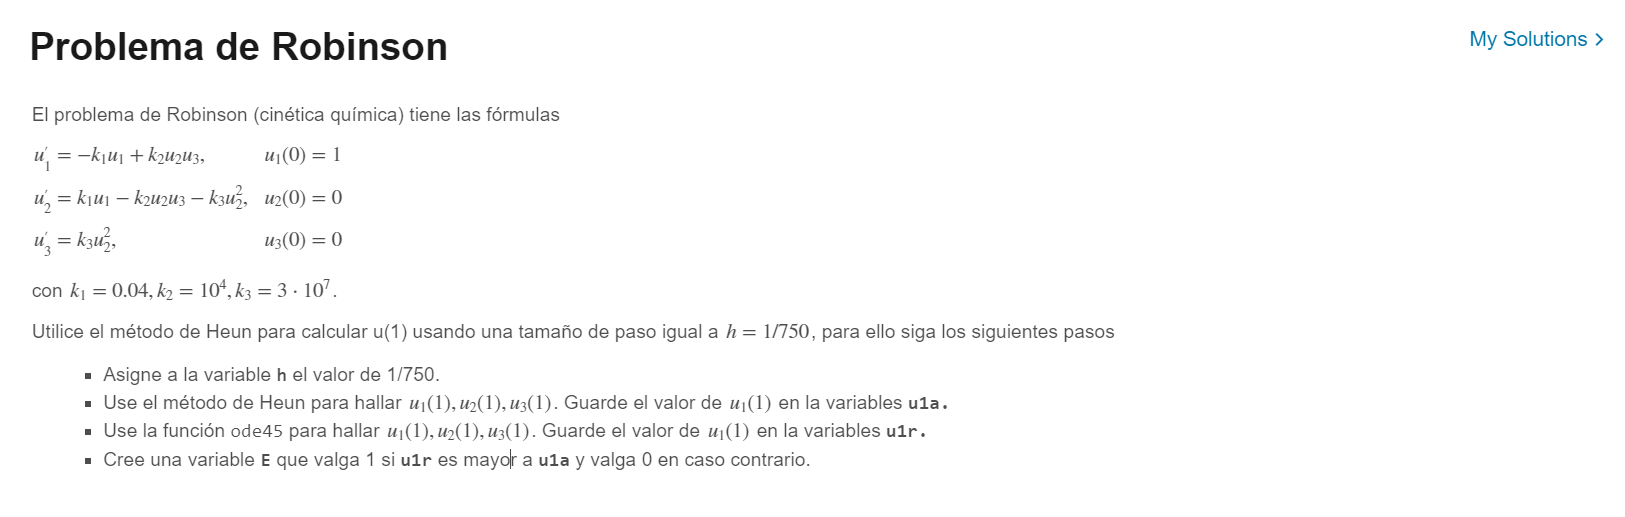

syms x y z
k1=0.04;k2=10^4;k3=3*10^7;
f=-k1*x+k2*y*z

$$f = 10000\,y\,z-\frac{x}{25}$$

g=k1*x-k2*y*z-k3*y^2

$$g = -30000000\,y^{2}-10000\,z\,y+\frac{x}{25}$$

q=k3*y^2

$$q = 30000000\,y^{2}$$

a=0;b=1;
[u1a]=heun(f,g,q,a,b,1,0,0,1/750,1)

u1a = 0.9646

[~,Sol]=ode45(@(t,y)odefun(t,y),[0,1],[1; 0; 0]);
u1r=Sol(end,1)

u1r = 0.9665

E=double(u1r>u1a)

E = 1

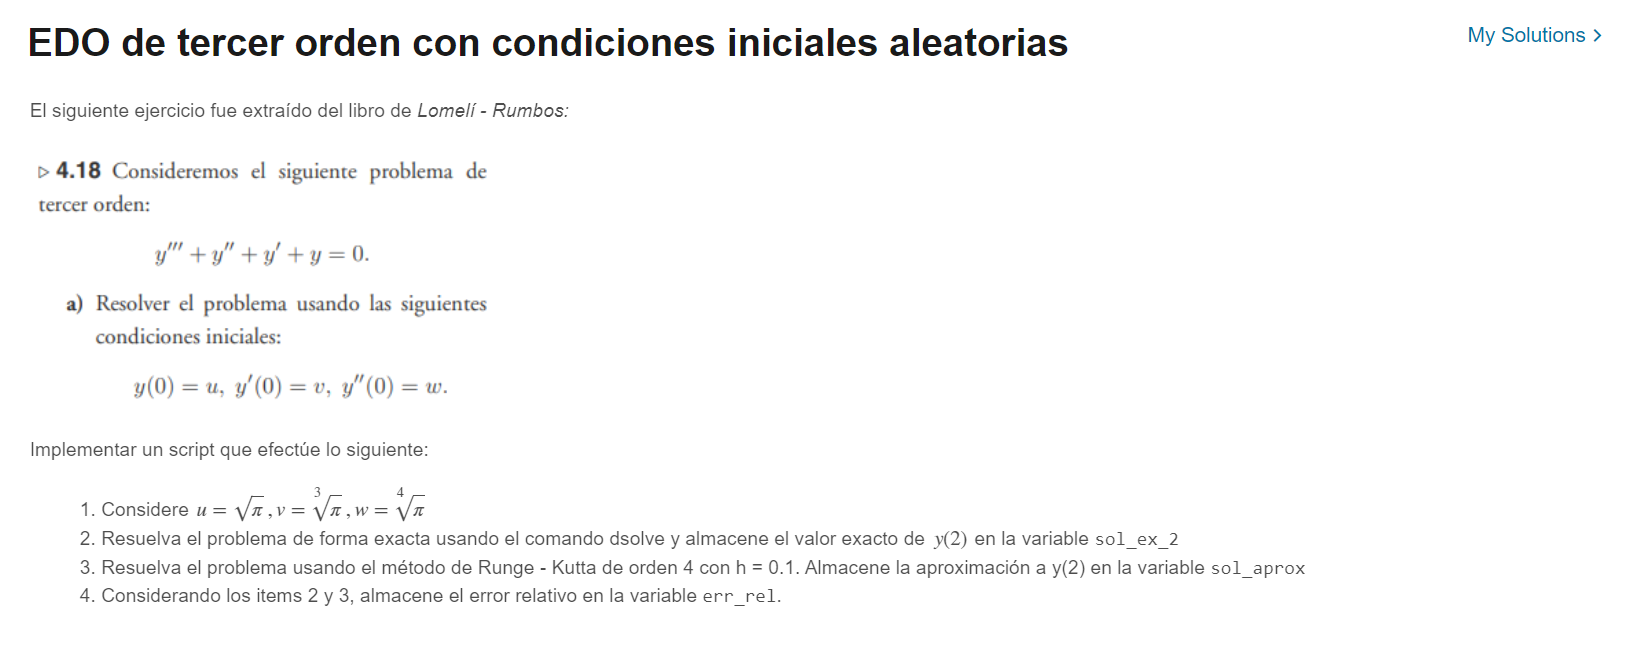

syms y(t)
D3y=diff(y,3);
D2y=diff(y,2);
Dy=diff(y);
Sol=matlabFunction(dsolve(D3y==-D2y-Dy-y,y(0)==sqrt(pi),Dy(0)==pi^(1/3),D2y(0)==pi^(1/4)));
sol_ex_2=Sol(2)

sol_ex_2 = 2.8611

syms x y z
f=y;
g=z;
q=-z-y-x;
sol_aprox=rk4_sistema_tres(f,g,q,0,2,sqrt(pi),pi^(1/3),pi^(1/4),0.1,2)

sol_aprox = 2.8611

err_rel=abs(sol_ex_2-sol_aprox)/abs(sol_ex_2)

err_rel = 8.4950e-07

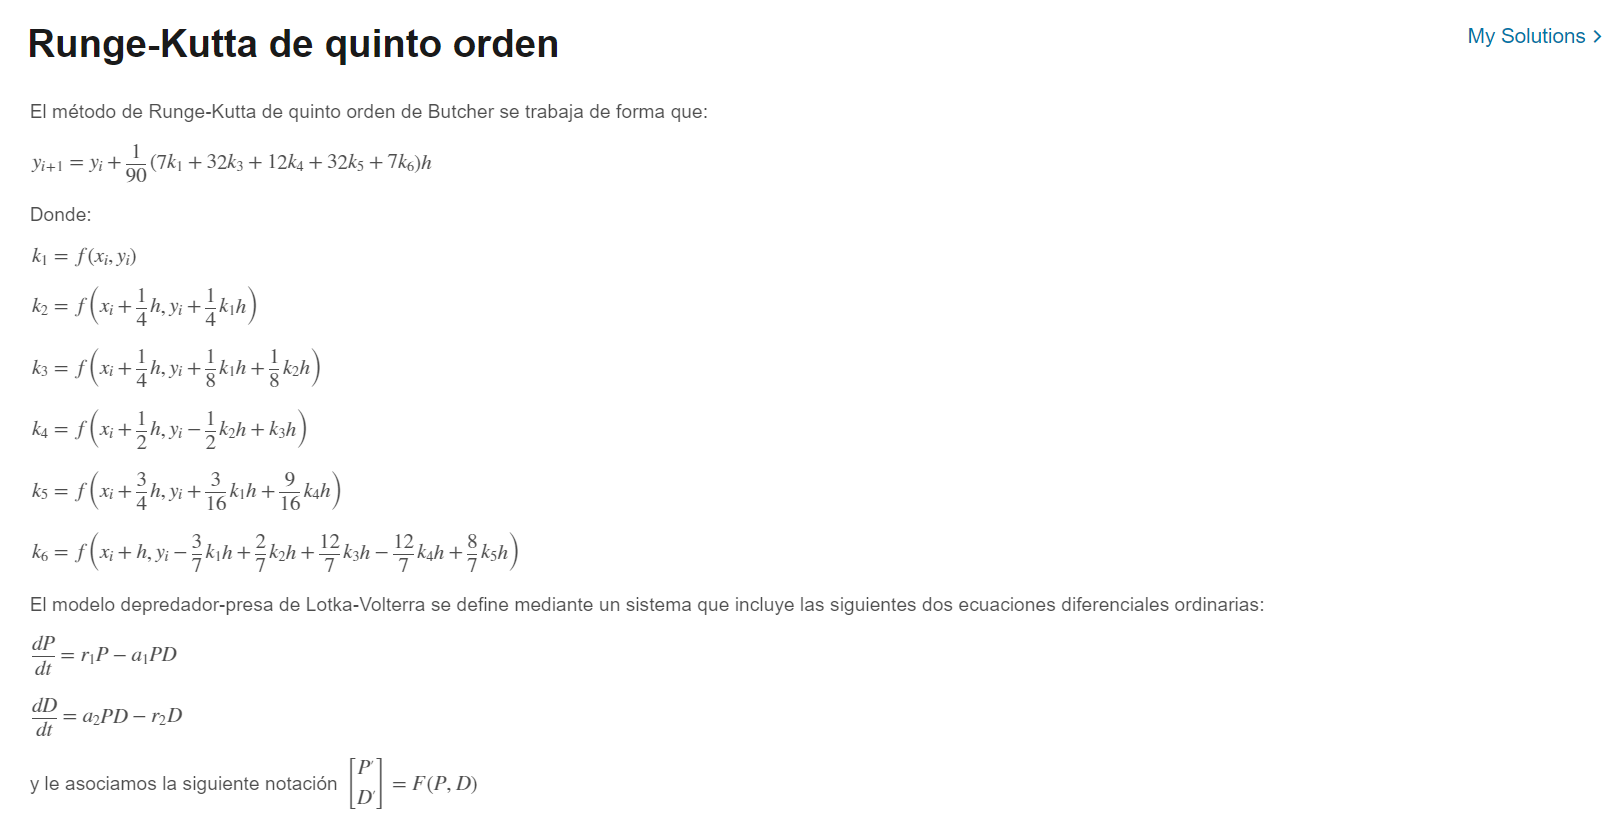

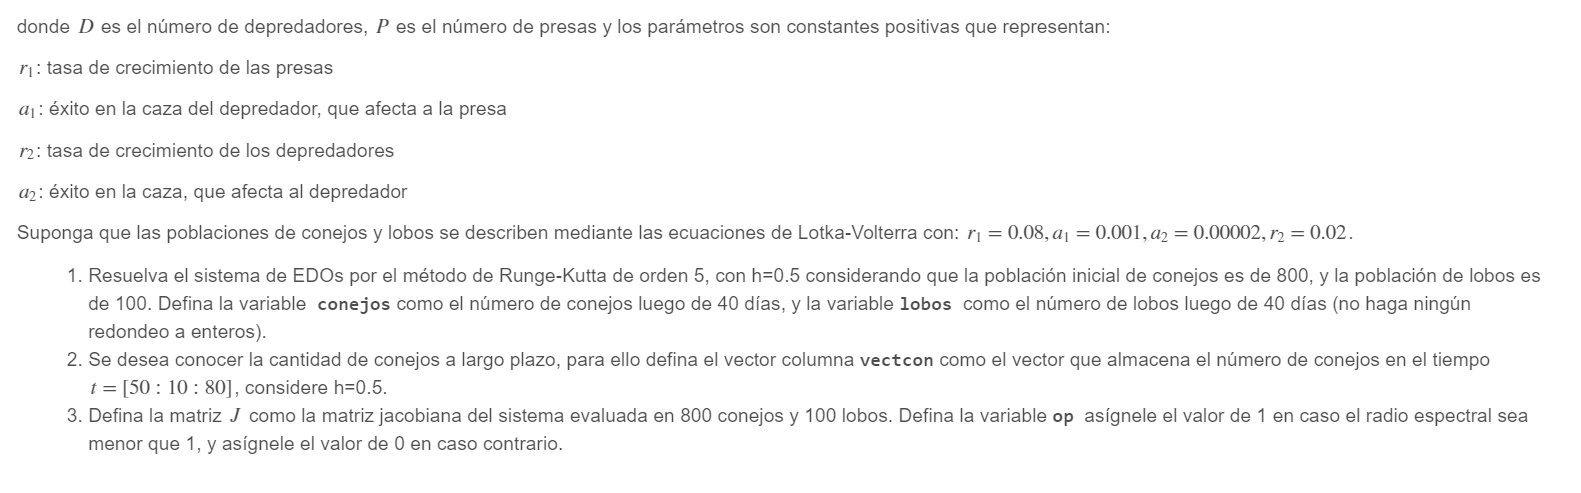

syms x y
r1=0.08;a1=0.001;a2=0.00002;r2=0.02;
f=r1*x-a1*x*y;
g=a2*x*y-r2*y;
[conejos,lobos]=rk5_sistema(f,g,0,40,800,100,0.5,40)

T = 81×3 table
     t       x         y   
    ___    ______    ______

      0       800       100
    0.5    792.08    99.796
      1    784.32    99.585
    1.5    776.72    99.367
      2    769.28    99.141
    2.5    761.99    98.909
      3    754.87    98.671
    3.5     747.9    98.426
      4    741.09    98.174
    4.5    734.43    97.917
      5    727.93    97.654
    5.5    721.58    97.386
      6    715.38    97.112
    6.5    709.34    96.833
      7    703.44    96.549
    7.5    697.69    96.261


conejos = 586.3842

lobos = 74.3676

[~,~,v]=rk5_sistema(f,g,0,80,800,100,0.5,80)

T = 161×3 table
     t       x         y   
    ___    ______    ______

      0       800       100
    0.5    792.08    99.796
      1    784.32    99.585
    1.5    776.72    99.367
      2    769.28    99.141
    2.5    761.99    98.909
      3    754.87    98.671
    3.5     747.9    98.426
      4    741.09    98.174
    4.5    734.43    97.917
      5    727.93    97.654
    5.5    721.58    97.386
      6    715.38    97.112
    6.5    709.34    96.833
      7    703.44    96.549
    7.5    697.69    96.261


t=(50:10:80)*2+1;
vectcon=v(t)
syms P D
f=r1*P-a1*P*D;
g=a2*D*P-r2*D;
F=[f;g];
F=matlabFunction(F);
J=matlabFunction(jacobian(F(D,P),[D,P]));
A=J(100,800)
D=diag(diag(A));
L=-tril(A,-1);
U=-triu(A,1);
Tj=(D)\(L+U);
Tgs=(D-L)\U;
radio_jacobi=max(abs(eig(Tj)))

radio_jacobi = 0.2236

radio_gauss=max(abs(eig(Tgs))) %menor a uno en ambos casos asi q :p

radio_gauss = 0.0500

op=1;

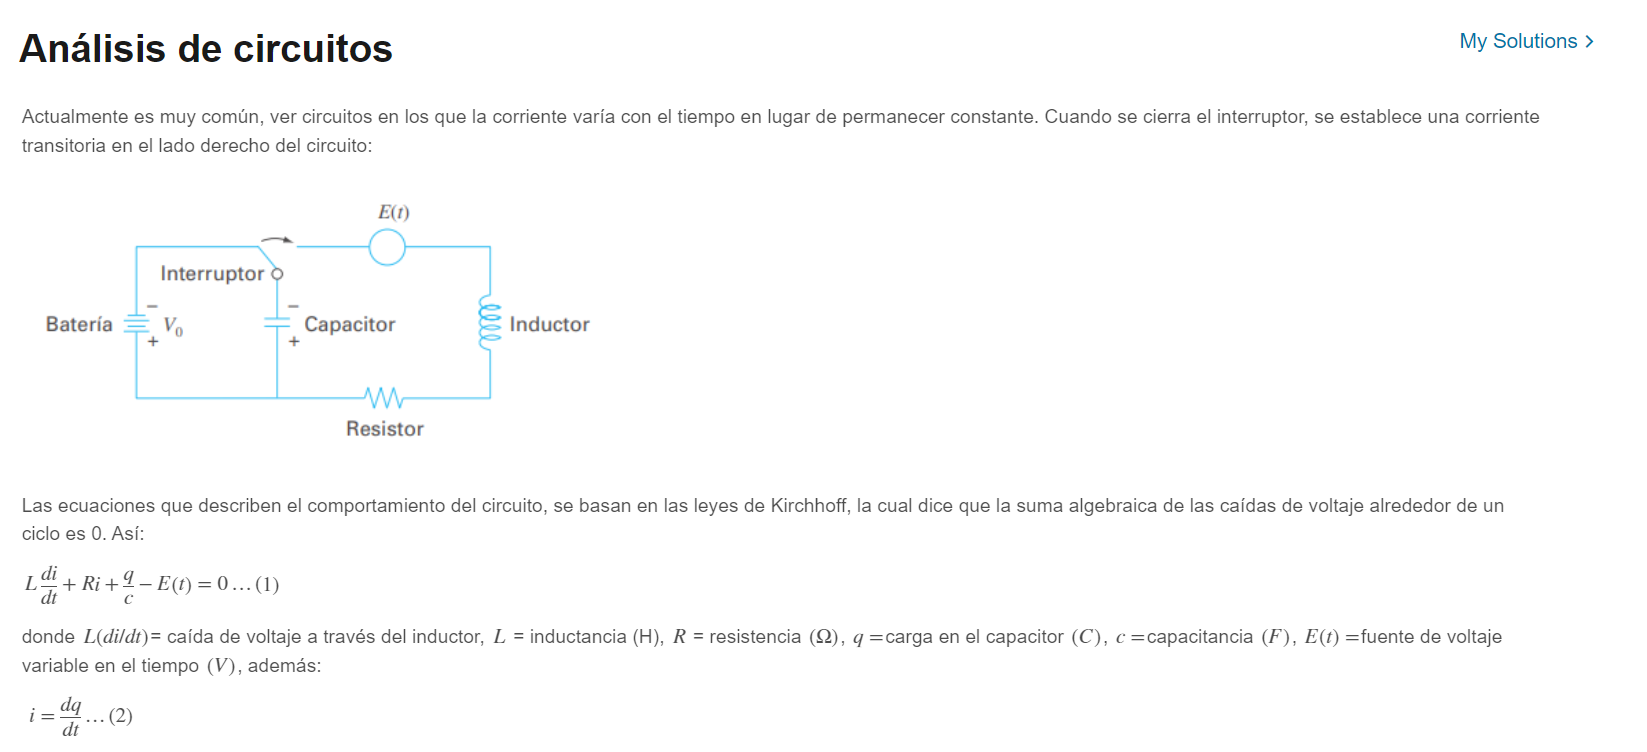

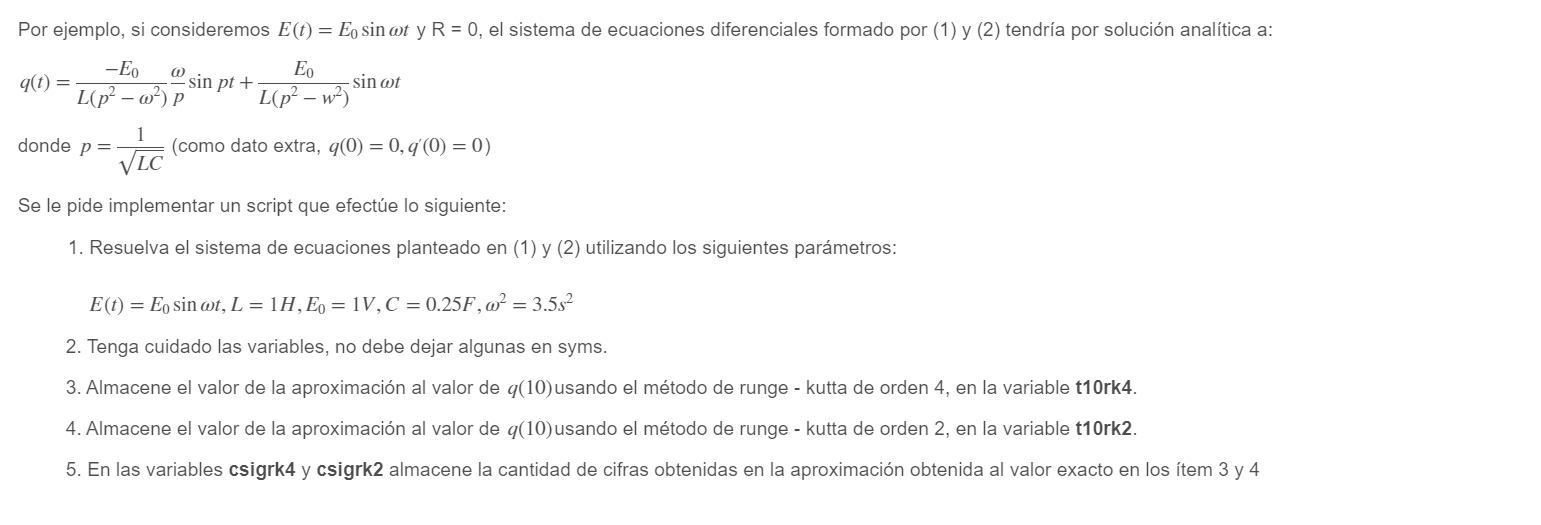

syms x y t
I=x;
q=y;
E0=1;w=sqrt(3.5);
L=1;C=0.25;R=0;
E=E0*sin(w*t);
f=(E-q/C-R*I)/L

$$f = \sin\left(\frac{\sqrt{2}\,\sqrt{7}\,t}{2}\right)-4\,y$$

g=I

$$g = x$$

[~,t10rk4]=rk4_sistema(f,g,0,10,0,0,0.1,10)

T = 101×7 table
     t         x            y         exacto_x      exacto_y       err_x         err_y   
    ___    _________    __________    _________    __________    __________    __________

      0            0             0            0             0             0             0
    0.1    0.0092958    0.00031135    0.0092958    0.00031064     2.845e-08    7.1318e-07
    0.2     0.036488     0.0024586     0.036488     0.0024572    5.2217e-07    1.3756e-06
    0.3      0.07953     0.0081399     0.079531      0.008138    1.4329e-06    1.8942e-06
    0.4      0.13514      0.018786      0.13514      0.018784    2.6613e-06    2.1871e-06
    0.5      0.19899      0.035444      0.19899      0.035442    4.0645e-06    2.1908e-06
    0.6      0.26594     

t10rk4 = -1.9897

[~,t10rk2]=rk2_sistema(f,g,0,10,0,0,0.1,10)

t10rk2 = -1.9151

p=1/(sqrt(L*C))

p = 2

fun=matlabFunction(-E0/(L*(p^2-w^2))*w/p*sin(p*t)+E0/(L*(p^2-w^2))*sin(w*t))

fun = function_handle with value:
    @(t)sin((sqrt(2.0).*sqrt(7.0).*t)./2.0).*2.0-(sqrt(2.0).*sqrt(7.0).*sin(t.*2.0))./2.0


qexact=fun(10)

qexact = -1.9896

n=1;
tope=5*10^-n;
er1=abs(qexact-t10rk4)/abs(qexact);
while er1<=tope
    n=n+1;
    tope=5*10^-n;
end
csigrk4=n-1

csigrk4 = 4

n=1;
tope=5*10^-n;
er2=abs(qexact-t10rk2)/abs(qexact);
while er2<=tope
    n=n+1;
    tope=5*10^-n;
end
csigrk2=n-1

csigrk2 = 2

    function dydt = odefun(t,y)
    k1=0.04;k2=10^4;k3=3*10^7;
    dydt = zeros(3,1);
    dydt(1) = -k1*y(1)+k2*y(2)*y(3);
    dydt(2) = k1*y(1)-k2*y(2)*y(3)-k3*y(2)^2;
    dydt(3) = k3*y(2)^2;
    end

function [x,y,t,r]=euler(f,g,a,b,f0,g0,h,val)
funx=matlabFunction(f,"Vars",{'t','x','y'});
funy=matlabFunction(g,"Vars",{'t','x','y'});
t=a:h:b;
iter=val/h;
z=[t(1) f0 g0];
for i=2:iter+1
x1=f0+h*funx(t(i-1),f0,g0);
y1=g0+h*funy(t(i-1),f0,g0);
z=[z;t(i) x1 y1];
f0=x1;
g0=y1;
end
x=z(end,2);
y=z(end,3);
t=z(:,2);
r=z(:,3);
end

function [x,y,t,r]=rk2_sistema(f,g,a,b,f0,g0,h,val)
funx=matlabFunction(f,"Vars",{'t','x','y'});
funy=matlabFunction(g,"Vars",{'t','x','y'});
syms t y(t) x(t) %variables de nuestra función
f=subs(f,{x,y},{x(t),y(t)});
g=subs(g,{x,y},{x(t),y(t)});
Sol=dsolve(diff(x,t)==f,diff(y,t)==g,x(0)==f0,y(0)==g0);
Solx=matlabFunction(Sol.x);
Soly=matlabFunction(Sol.y);
t=a:h:b;
iter=val/h;
z=[t(1) f0 g0 Solx(t(1)) Soly(t(1)) abs(Solx(t(1))-f0) abs(Soly(t(1))-g0)];
for i=2:iter+1
k1x=funx(t(i-1),f0,g0);
k1y=funy(t(i-1),f0,g0);
k2x=funx(t(i-1)+h,f0+h*k1x,g0+h*k1y);
k2y=funy(t(i-1)+h,f0+h*k1x,g0+h*k1y);
x1=f0+(h/2)*(k1x+k2x);
y1=g0+(h/2)*(k1y+k2y);
z=[z;t(i) x1 y1 Solx(t(i)) Soly(t(i)) abs(Solx(t(i))-x1) abs(Soly(t(i))-y1)];
f0=x1;
g0=y1;
end
x=z(end,2);
y=z(end,3);
t=z(:,2);
r=z(:,3);
%T=array2table(z,'VariableNames',{'t','x','y','exacto_x','exacto_y','err_x','err_y'})
end

function [x,y]=rk4_sistema(f,g,a,b,f0,g0,h,val)
funx=matlabFunction(f,"Vars",{'t','x','y'});
funy=matlabFunction(g,"Vars",{'t','x','y'});
syms t y(t) x(t) %variables de nuestra función
f=subs(f,{x,y},{x(t),y(t)});
g=subs(g,{x,y},{x(t),y(t)});
Sol=dsolve(diff(x,t)==f,diff(y,t)==g,x(0)==f0,y(0)==g0);
Solx=matlabFunction(Sol.x);
Soly=matlabFunction(Sol.y);
t=a:h:b;
iter=val/h;
z=[t(1) f0 g0 Solx(t(1)) Soly(t(1)) abs(Solx(t(1))-f0) abs(Soly(t(1))-g0)];
for i=2:iter+1
k1x=funx(t(i-1),f0,g0);
k1y=funy(t(i-1),f0,g0);
k2x=funx(t(i-1)+h/2,f0+h/2*k1x,g0+h/2*k1y);
k2y=funy(t(i-1)+h/2,f0+h/2*k1x,g0+h/2*k1y);
k3x=funx(t(i-1)+h/2,f0+h/2*k2x,g0+h/2*k2y);
k3y=funy(t(i-1)+h/2,f0+h/2*k2x,g0+h/2*k2y);
k4x=funx(t(i-1)+h,f0+k3x*h,g0+k3y*h);
k4y=funy(t(i-1)+h,f0+k3x*h,g0+k3y*h);
x1=f0+(h/6)*(k1x+2*k2x+2*k3x+k4x);
y1=g0+(h/6)*(k1y+2*k2y+2*k3y+k4y);
z=[z;t(i) x1 y1 Solx(t(i)) Soly(t(i)) abs(Solx(t(i))-x1) abs(Soly(t(i))-y1)];
f0=x1;
g0=y1;
end
x=z(end,2);
y=z(end,3);
T=array2table(z,'VariableNames',{'t','x','y','exacto_x','exacto_y','err_x','err_y'})
end

function [x,y,z,t,r,q]=heun(f,g,q,a,b,f0,g0,h0,h,val)
funx=matlabFunction(f,"Vars",{'t','x','y','z'});
funy=matlabFunction(g,"Vars",{'t','x','y','z'});
funz=matlabFunction(q,"Vars",{'t','x','y','z'});
t=a:h:b;
iter=val/h;
Z=[t(1) f0 g0 h0];
for i=2:iter+1
k1x=funx(t(i-1),f0,g0,h0);
k1y=funy(t(i-1),f0,g0,h0);
k1z=funz(t(i-1),f0,g0,h0);
k2x=funx(t(i-1)+h,f0+h*k1x,g0+h*k1y,h0+h*k1z);
k2y=funy(t(i-1)+h,f0+h*k1x,g0+h*k1y,h0+h*k1z);
k2z=funz(t(i-1)+h,f0+h*k1x,g0+h*k1y,h0+h*k1z);
x1=f0+(h/2)*(k1x+k2x);
y1=g0+(h/2)*(k1y+k2y);
z1=h0+(h/2)*(k1z+k2z);
Z=[Z;t(i) x1 y1 z1];
f0=x1;
g0=y1;
h0=z1;
end
x=Z(end,2);
y=Z(end,3);
z=Z(end,4);
t=Z(:,2);
r=Z(:,3);
q=Z(:,4);
end

function [x,y,z]=rk4_sistema_tres(f,g,q,a,b,f0,g0,h0,h,val)
funx=matlabFunction(f,"Vars",{'t','x','y','z'});
funy=matlabFunction(g,"Vars",{'t','x','y','z'});
funz=matlabFunction(q,"Vars",{'t','x','y','z'});
t=a:h:b;
iter=val/h;
Z=[t(1) f0 g0 h0];
for i=2:iter+1
k1x=funx(t(i-1),f0,g0,h0);
k1y=funy(t(i-1),f0,g0,h0);
k1z=funz(t(i-1),f0,g0,h0);
k2x=funx(t(i-1)+h/2,f0+h/2*k1x,g0+h/2*k1y,h0+h/2*k1z);
k2y=funy(t(i-1)+h/2,f0+h/2*k1x,g0+h/2*k1y,h0+h/2*k1z);
k2z=funz(t(i-1)+h/2,f0+h/2*k1x,g0+h/2*k1y,h0+h/2*k1z);
k3x=funx(t(i-1)+h/2,f0+h/2*k2x,g0+h/2*k2y,h0+h/2*k2z);
k3y=funy(t(i-1)+h/2,f0+h/2*k2x,g0+h/2*k2y,h0+h/2*k2z);
k3z=funz(t(i-1)+h/2,f0+h/2*k2x,g0+h/2*k2y,h0+h/2*k2z);
k4x=funx(t(i-1)+h,f0+k3x*h,g0+k3y*h,h0+k3z*h);
k4y=funy(t(i-1)+h,f0+k3x*h,g0+k3y*h,h0+k3z*h);
k4z=funz(t(i-1)+h,f0+k3x*h,g0+k3y*h,h0+k3z*h);
x1=f0+(h/6)*(k1x+2*k2x+2*k3x+k4x);
y1=g0+(h/6)*(k1y+2*k2y+2*k3y+k4y);
z1=h0+(h/6)*(k1z+2*k2z+2*k3z+k4z);
Z=[Z;t(i) x1 y1 z1];
f0=x1;
g0=y1;
h0=z1;
end
x=Z(end,2);
y=Z(end,3);
z=Z(end,4);
end

function [x,y,t]=rk5_sistema(f,g,a,b,f0,g0,h,val)
funx=matlabFunction(f,"Vars",{'t','x','y'});
funy=matlabFunction(g,"Vars",{'t','x','y'});
t=a:h:b;
iter=val/h;
z=[t(1) f0 g0];
for i=2:iter+1
k1x=funx(t(i-1),f0,g0);
k1y=funy(t(i-1),f0,g0);
k2x=funx(t(i-1)+h/4,f0+h/4*k1x,g0+h/4*k1y);
k2y=funy(t(i-1)+h/4,f0+h/4*k1x,g0+h/4*k1y);
k3x=funx(t(i-1)+h/4,f0+h/8*k1x+h/8*k2x,g0+h/8*k1y+h/8*k2y);
k3y=funy(t(i-1)+h/4,f0+h/8*k1x+h/8*k2x,g0+h/8*k1y+h/8*k2y);
k4x=funx(t(i-1)+h/2,f0-h/2*k2x+h*k3x,g0-h/2*k2y+h*k3y);
k4y=funy(t(i-1)+h/2,f0-h/2*k2x+h*k3x,g0-h/2*k2y+h*k3y);
k5x=funx(t(i-1)+3*h/4,f0+3*h/16*k1x+9*h/16*k4x,g0+3*h/16*k1y+9*h/16*k4y);
k5y=funy(t(i-1)+3*h/4,f0+3*h/16*k1x+9*h/16*k4x,g0+3*h/16*k1y+9*h/16*k4y);
k6x=funx(t(i-1)+h,f0-3*h/7*k1x+2*h/7*k2x+12/7*h*k3x-12/7*h*k4x+8/7*k5x*h,g0-3*h/7*k1y+2*h/7*k2y+12/7*h*k3y-12/7*h*k4y+8/7*k5y*h);
k6y=funy(t(i-1)+h,f0-3*h/7*k1x+2*h/7*k2x+12/7*h*k3x-12/7*h*k4x+8/7*k5x*h,g0-3*h/7*k1y+2*h/7*k2y+12/7*h*k3y-12/7*h*k4y+8/7*k5y*h);
x1=f0+(h/90)*(7*k1x+32*k3x+12*k4x+32*k5x+7*k6x);
y1=g0+(h/90)*(7*k1y+32*k3y+12*k4y+32*k5y+7*k6y);
z=[z;t(i) x1 y1];
f0=x1;
g0=y1;
end
x=z(end,2);
y=z(end,3);
t=z(:,2);
T=array2table(z,'VariableNames',{'t','x','y'})
end